# Implicit Deep Learning Tutorial on House price prediction dataset

clear all;
addpath([pwd,'/datasets/house_prices'])
[Y, Y_factor, U, U_test , feature_names] = process_house_prices_data();

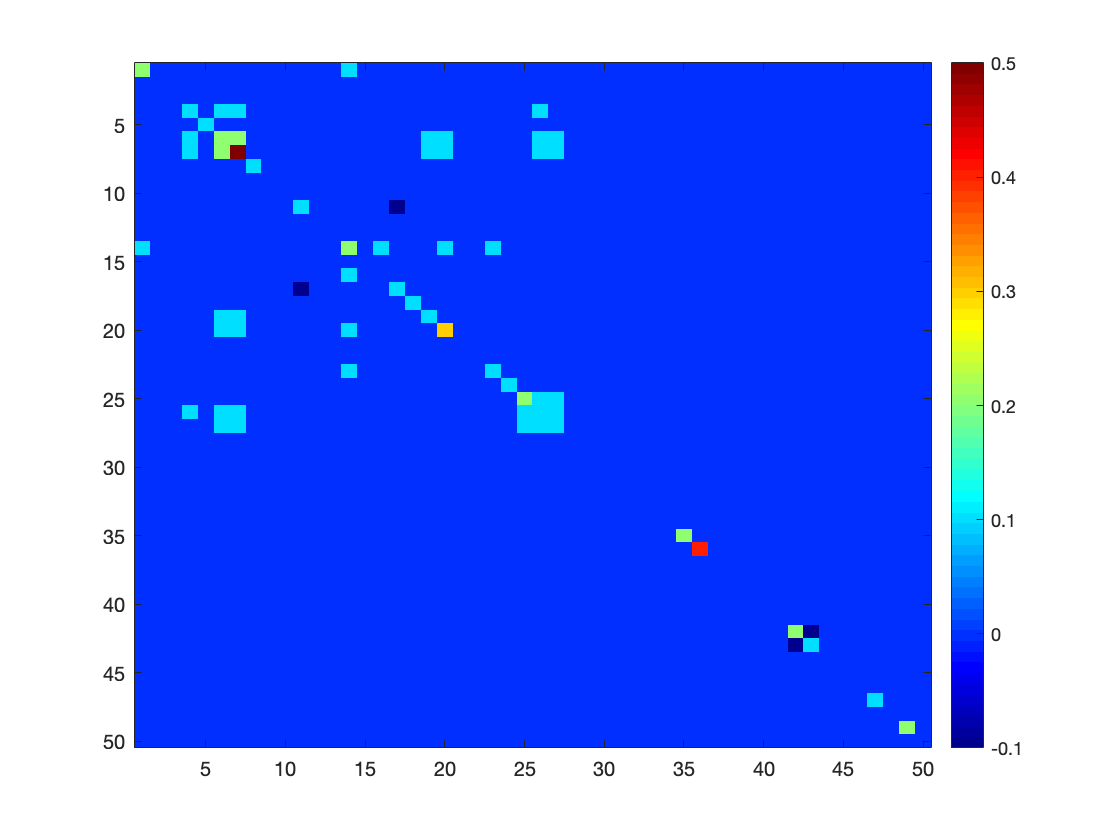

close all;
C = round(cov(U(1:50,:)'),1);
colormap('jet')
imagesc(C)
colorbar

[n,m] = size(U);
permutation = randperm(m);
% permute the data using this permutation vector
Y = Y(permutation); Y_train = Y(1:floor(3*m/4)); Y_validation = Y(ceil(3*m/4):m);
U = U(:,permutation); U_train = U(:,1:floor(3*m/4)); U_validation = U(:,ceil(3*m/4):m);
m_train = size(Y_train,2); m_validation = size(Y_validation,2);

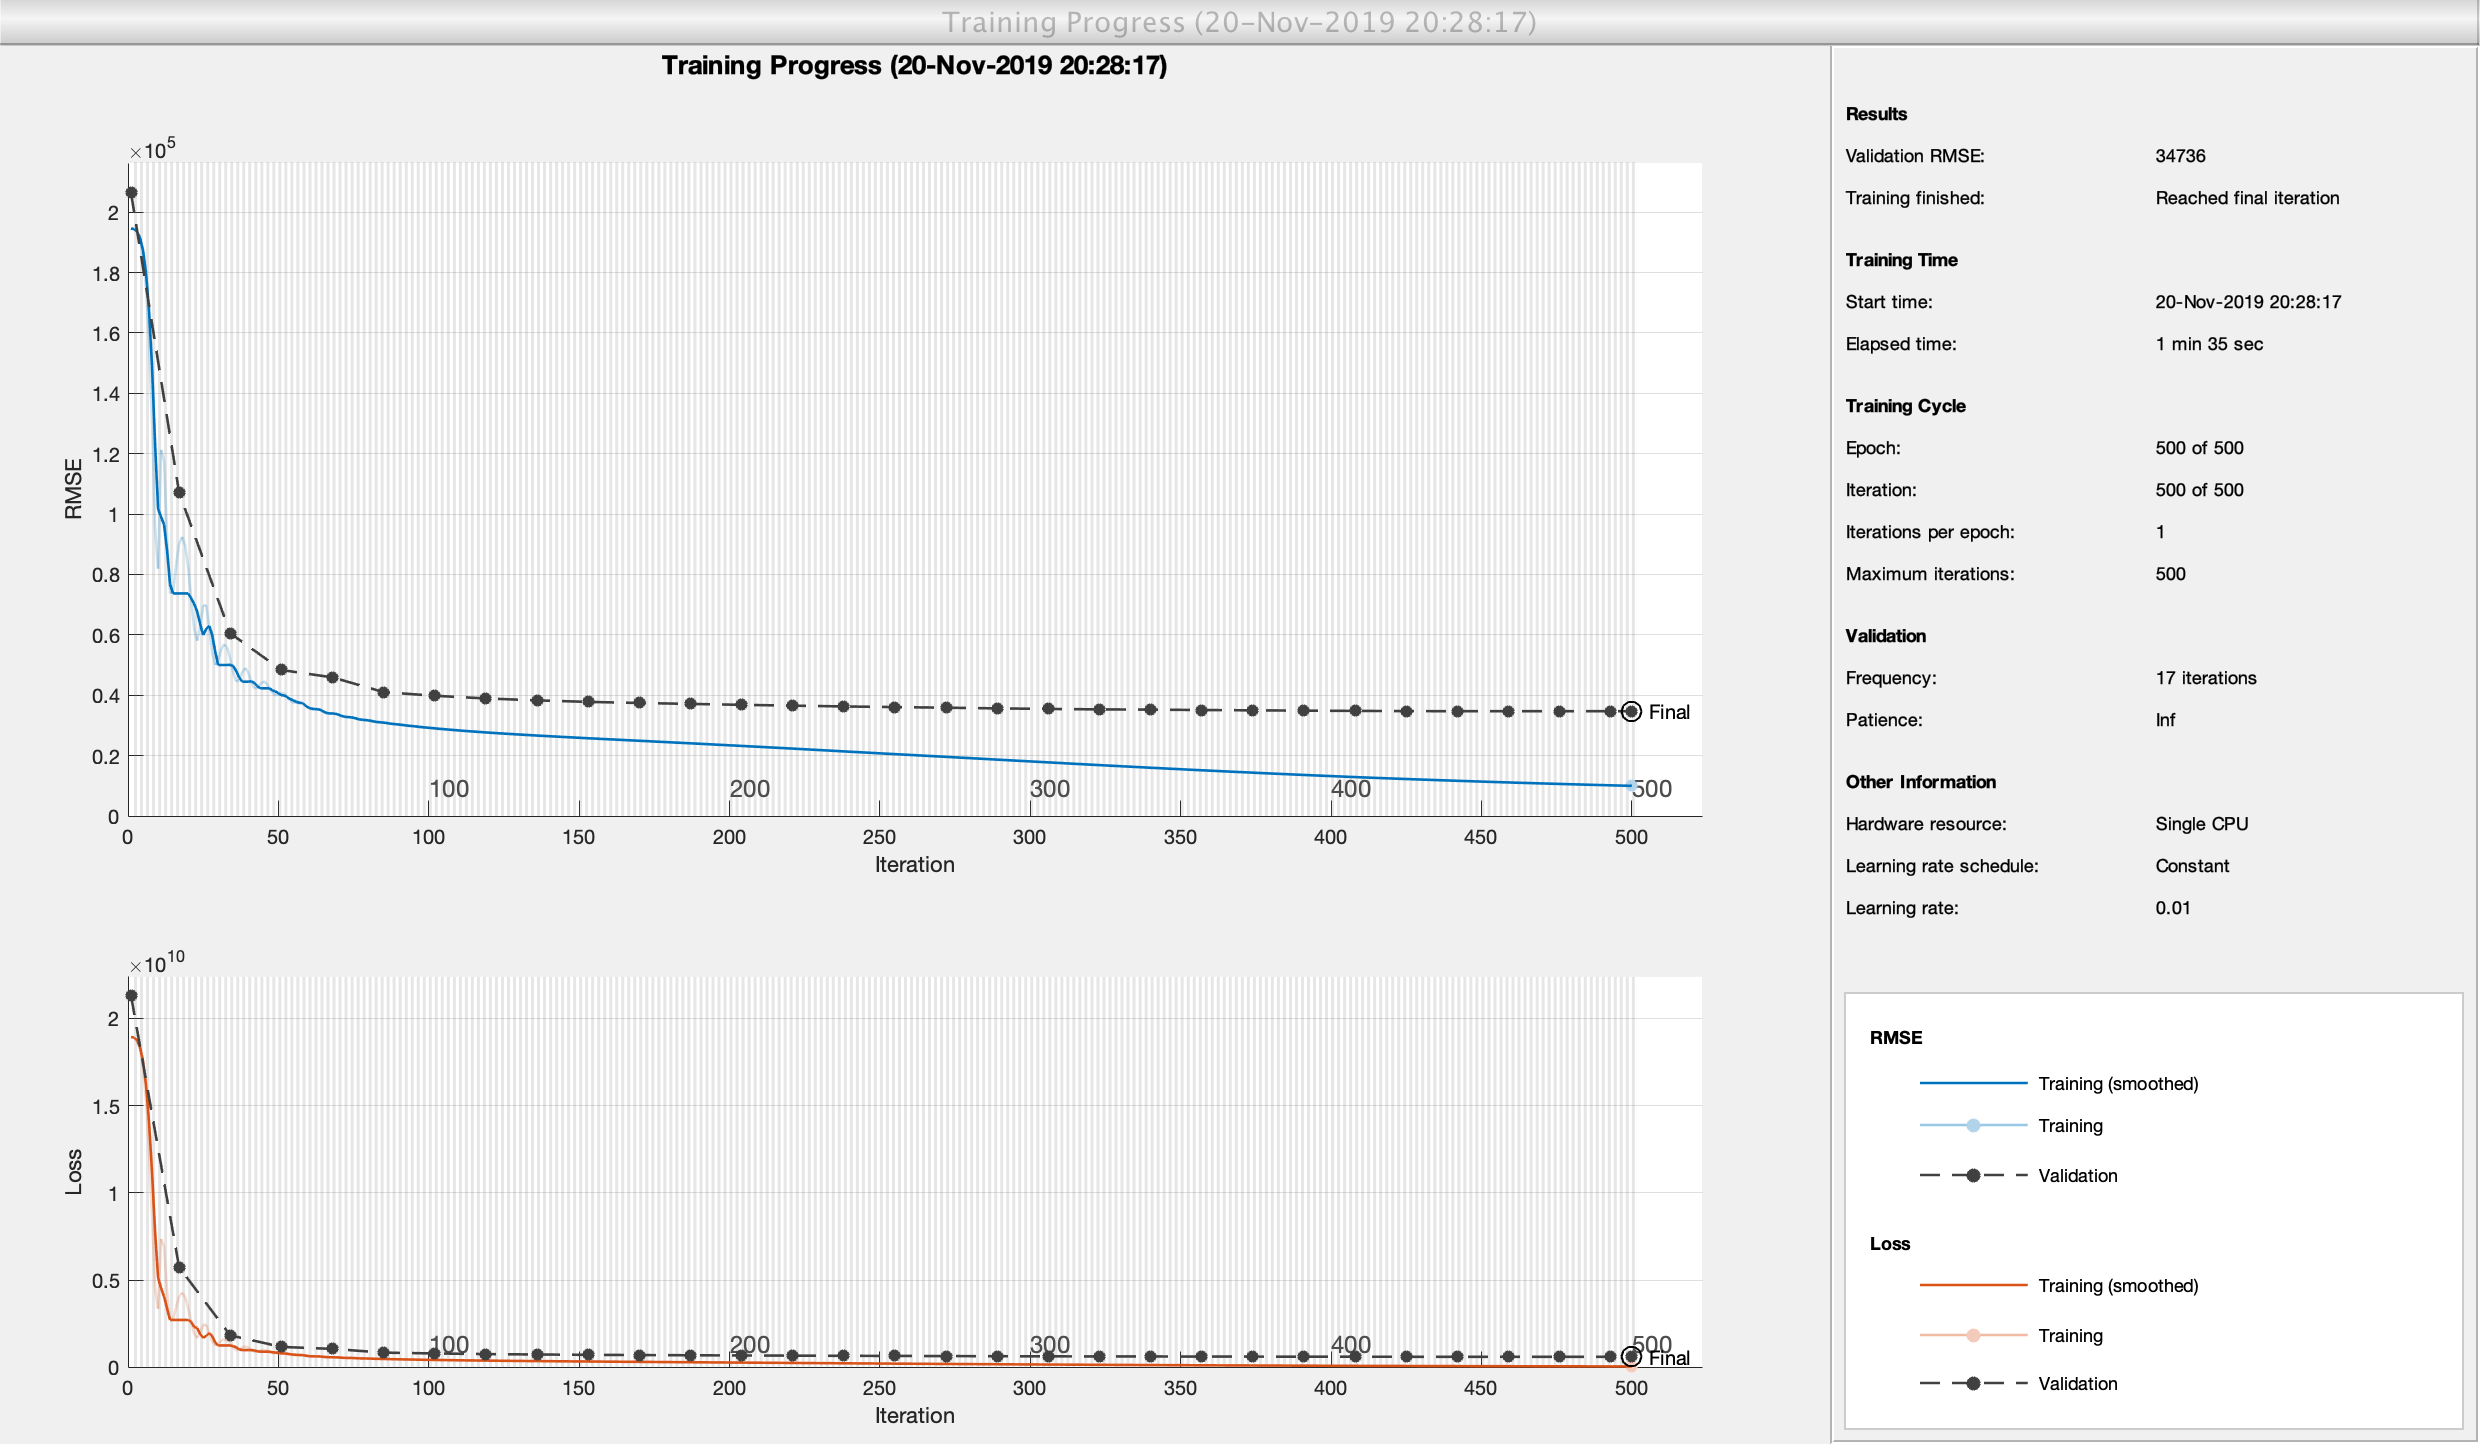

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |    194604.09 |    206476.00 |   1.8935e+10 |   2.1316e+10 |          0.0100 |
|      17 |          17 |       00:00:04 |     90246.09 |    107103.95 |   4.0722e+09 |   5.7356e+09 |          0.0100 |
|      34 |          34 |       00:00:07 |     52003.59 |     60530.77 |   1.3522e+09 |   1.8320e+09 |          0.0100 |
|      50 |          50 |       00:00:10 |     40280.24 |              |   8.1125e+08 |              |          0.0100 |
|      5

close all;
layers = [
    sequenceInputLayer(n)
    fullyConnectedLayer(3*n)
    reluLayer 
    fullyConnectedLayer(2*n)
    reluLayer
    fullyConnectedLayer(2*n)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];
max_epochs= 2*10^2;
validationFrequency = ceil(max_epochs/30);
options = trainingOptions('adam','MaxEpochs',max_epochs,'MiniBatchSize',40,'InitialLearnRate',10^-2, ...
    'ValidationData',{U_validation,Y_validation}, 'ValidationFrequency',validationFrequency,'Plots','training-progress', 'L2Regularization', 1);
net = trainNetwork(U,Y,layers,options);

Y_predicted = Y_factor*predict(net,U_test); 
T=cell(size(U_test,2)+1,2);
T{1,1}='Id'; T{1,2}='SalePrice';
for k = 1:size(U_test,2)
    T{k+1,1} = 1460+k;
    T{k+1,2} = Y_predicted(k)
end